# Heat Diffusion on Rod

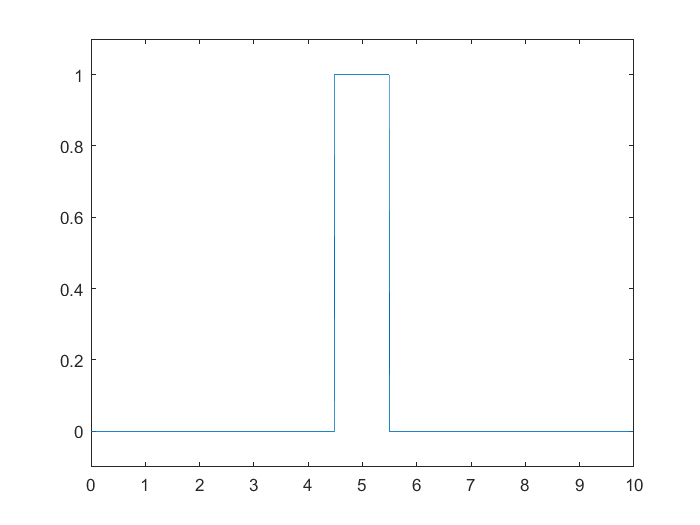

clear;clc;
dx = 0.01;
L = 10;
x = 0:dx:L-dx;
a = 0.2;
fx = zeros(size(x));
N = length(x);
fx(4.5*N/L:5.5*N/L) = 1;
figure(1);
plot(x,fx);
axis([0 10 -0.1 1.1]);

## Diffusion using Convolution

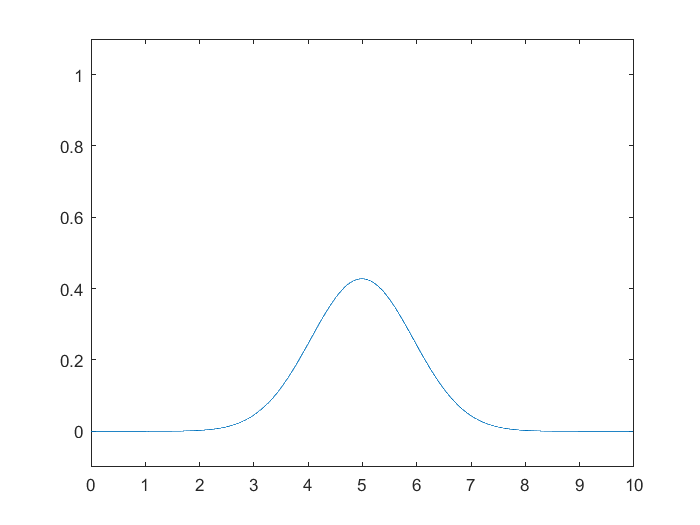

u = zeros(size(x));
dt = 0.1;
for k=1:100
    t = k*dt;
    for i=1:length(u)
        g = exp(-(x(i)-x).^2/(4*a^2*t))/(2*a*sqrt(pi*t));
        u(i) = dot(g,fx)*dx;
    end
    figure(2);
    plot(x,u);
    axis([0 10 -0.1 1.1]);
    drawnow;
    pause(0.1);
end

## Diffusion using FFT

uk = zeros(size(x));
fk = fft(fx,N);
dt = 0.1;
for k=1:100
    t = k*dt;
    w = (2*pi/L)*(-N/2:N/2-1); % Range of frequencies considered by matlab fft function
    w = fftshift(w); % This makes the order aligned with that of matlab
    uk = fk.*exp(-(a^2)*t*w.^2);
    u = ifft(uk,N);
    figure(3);
    plot(x,u);
    axis([0 10 -0.1 1.1]);
    drawnow;
    pause(0.1);
end